% Script main - Live - script Demo
% Main preproc/analysis script lernit to create PhysIO regressors and
% assess them via a nuisance-only GLM
%
%  main.mlx
%  to be run in results/>subjectID<


% Author:   Johanna Bayer, supervised by Lars Kasper
% Created:  2023-04-01
% Copyright (C) 2023

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Setup paths - #MOD# Modify to your own environment

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

subjectId = 'sub-01'; % subject ID default sub-01
nSlices = 36; % nSlicesTotal/MB factor default 36
TR = 2; % seconds default 2.0
nVolumes = 153;% number of volumes default is 153
sampling_interval = 0.01;% sampling interval default 0.01


% if true, only the SPM batch jobs are loaded, but you have to run them manually in the batch editor (play button)
isInteractive = true; % SPM interactive

hasStruct = true; % if false, uses (bias-corrected) mean of fmri.nii for visualizations
doSmooth =  false;

% specify the path to your SPM installtion
pathSPM = '/Users/jobayer/Documents/MATLAB/PhysIO-Live/libs/spm';

pathSPM = '/Users/jobayer/Documents/MATLAB/PhysIO-Live/libs/spm'

pathTAPAS = '/Users/jobayer/Documents/MATLAB/PhysIO-Live/libs/tapas';

pathTAPAS = '/Users/jobayer/Documents/MATLAB/PhysIO-Live/libs/tapas'




%specify your project
pathProject     = '/Users/jobayer/Documents/MATLAB/PhysIO-Live';
pathCode        = fullfile(pathProject, 'code');
pathResults     = fullfile(pathProject, 'results');
pathSubject     = fullfile(pathProject, 'results', subjectId);


addpath(genpath(pathCode));
pathNow = pwd;

cd(pathSubject);

% folder structure created with in results folder of subject to hold
% different preprocessed data
mkdir('glm')

mkdir('nifti')

mkdir('glm_s3')

mkdir('physio_out')


copyfile sub-01_ses-auditoryperception_func_sub-01_ses-auditoryperception_task-auditoryperception_run-01_bold.nii nifti/bold.nii
copyfile sub-01_ses-forrestgump_anat_sub-01_ses-forrestgump_T1w.nii nifti/T1w.nii

% add SPM path and tapas path
addpath(pathSPM)
addpath(genpath(pathTAPAS))

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Setup SPM Batch editor

 ___  ____  __  __                                            
/ __)(  _ \(  \/  )                                           
\__ \ )___/ )    (   Statistical Parametric Mapping           
(___/(__)  (_/\/\_)  SPM12 - https://www.fil.ion.ucl.ac.uk/spm/


SPM12: v12.6                                       17:41:25 - 21/05/2023
Initialising SPM                        :                   ..Duplicate application tag in applications 'SPM' and 'SPM'.
Duplicate application tag in applications 'BasicIO' and 'BasicIO'.
......

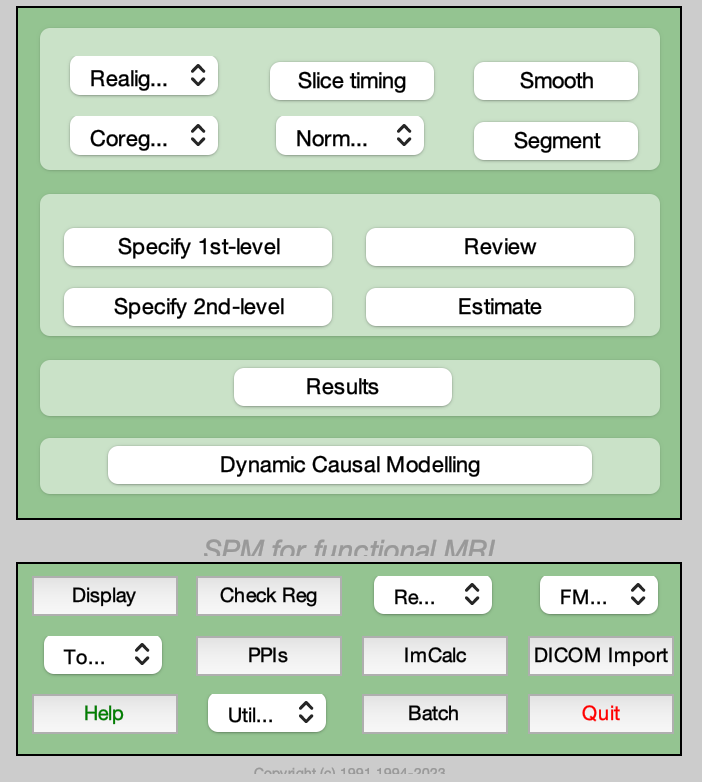

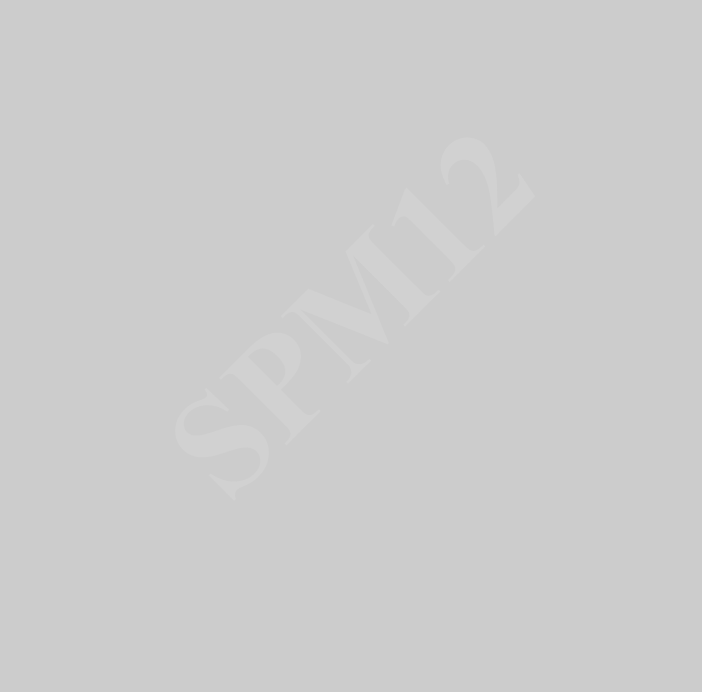

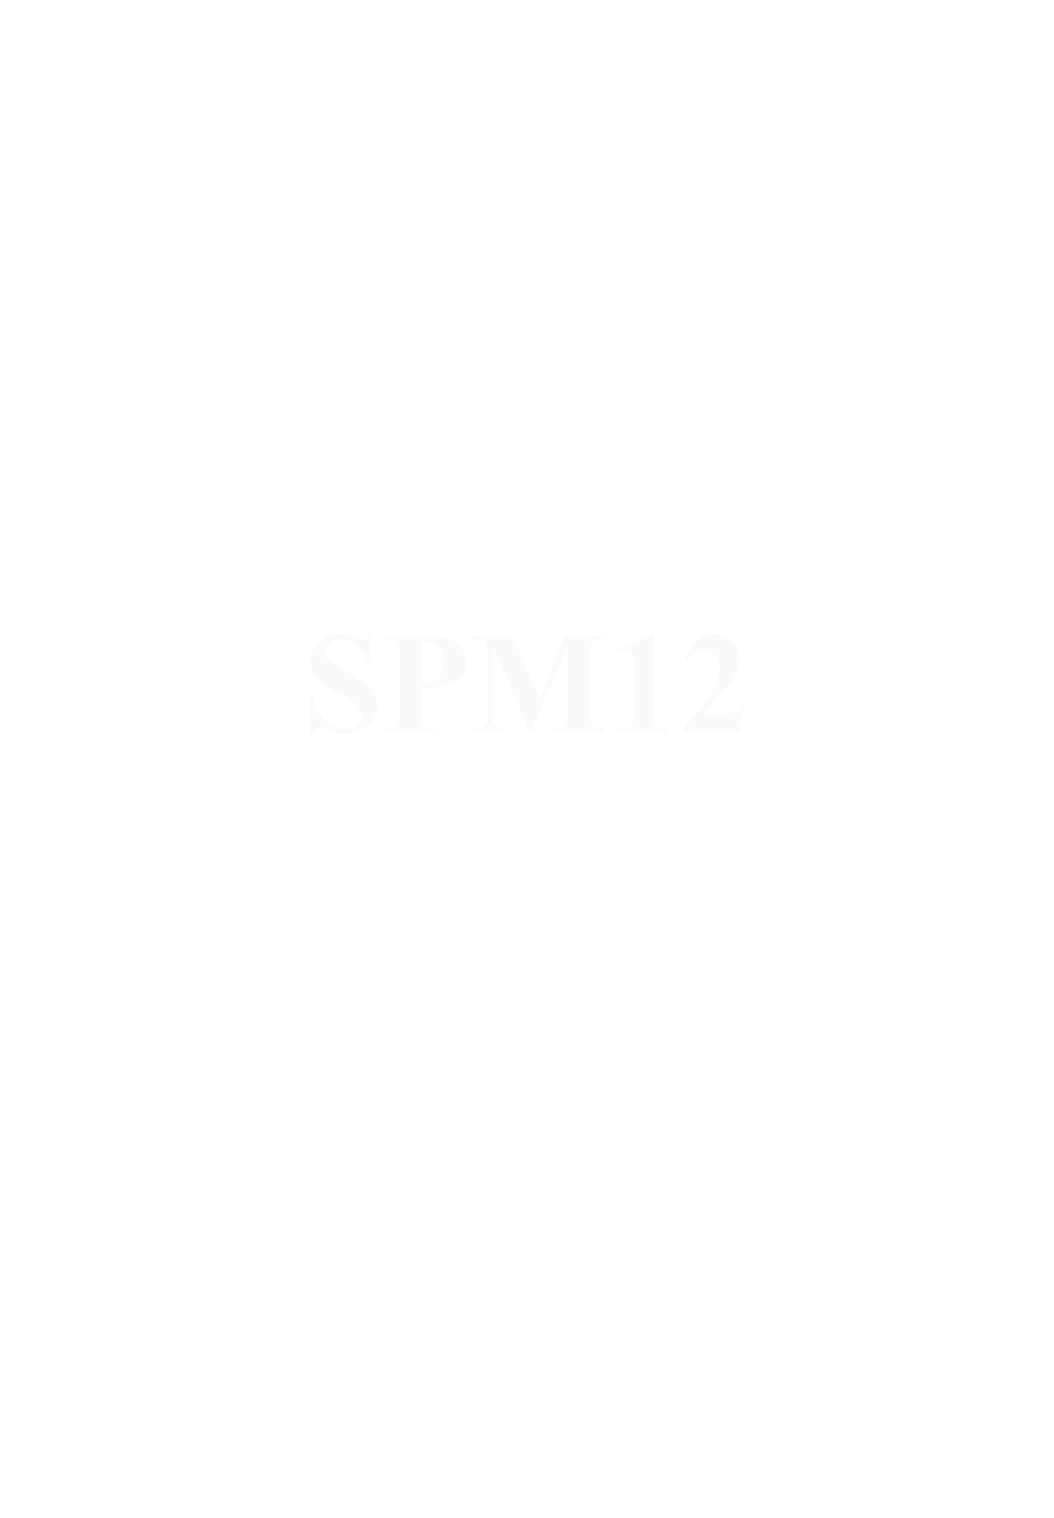

done

SPM present working directory:
	/Users/jobayer/Documents/MATLAB/PhysIO-Live/results/sub-01


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% spm_jobman('initcfg')
spm fmri


if isInteractive
    jobMode = 'interactive';
else
    jobMode = 'run';
end


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Spatial Preproc

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
if hasStruct
    fileJobPreproc = 'preproc_minimal_spm_job.m'; % generic path
else
    fileJobPreproc = 'preproc_minimal_no_struct_spm_job.m'; % use bias corrected mean of fmri.nii for viz
end

% loads matlabbatch and adapts subject-specific data
%clear matlabbatch
run(fileJobPreproc)

spm_jobman(jobMode, matlabbatch)

Item spm: No field(s) named
spatial



if isInteractive, input('Press Enter to continue'); end



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Physio

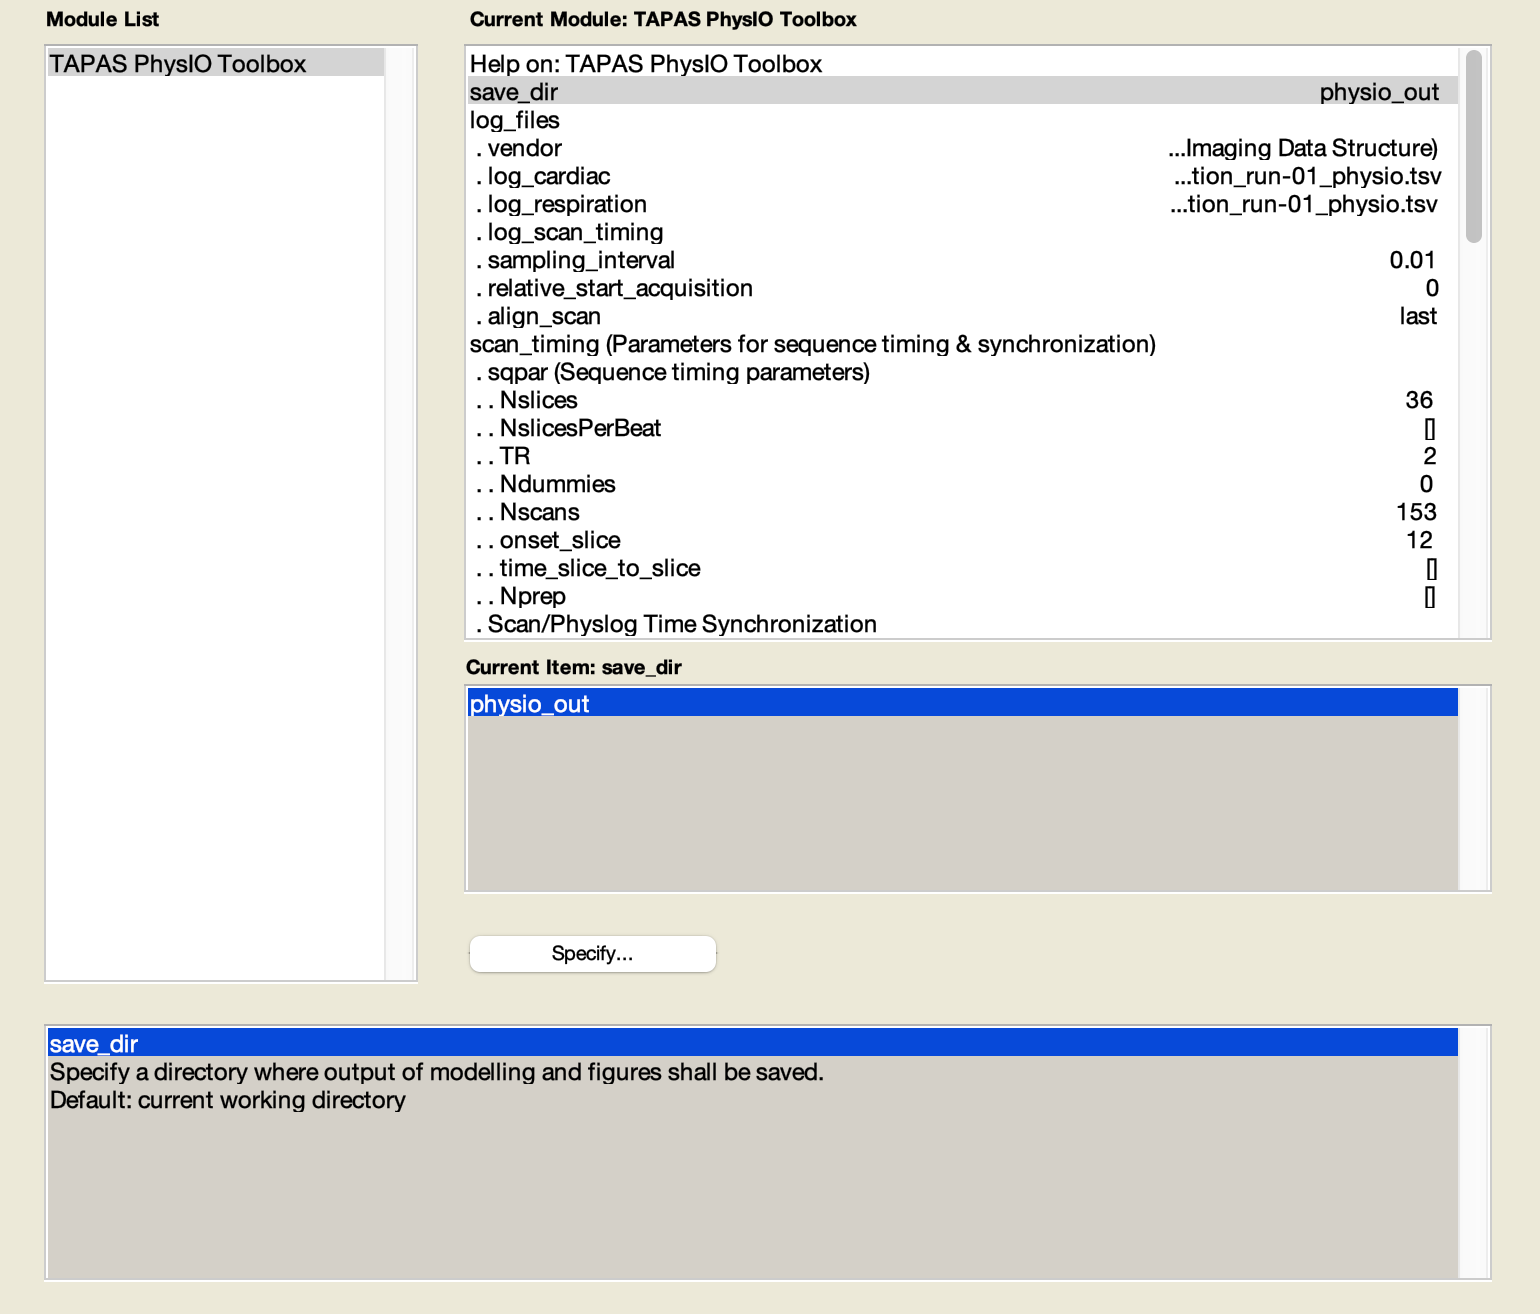

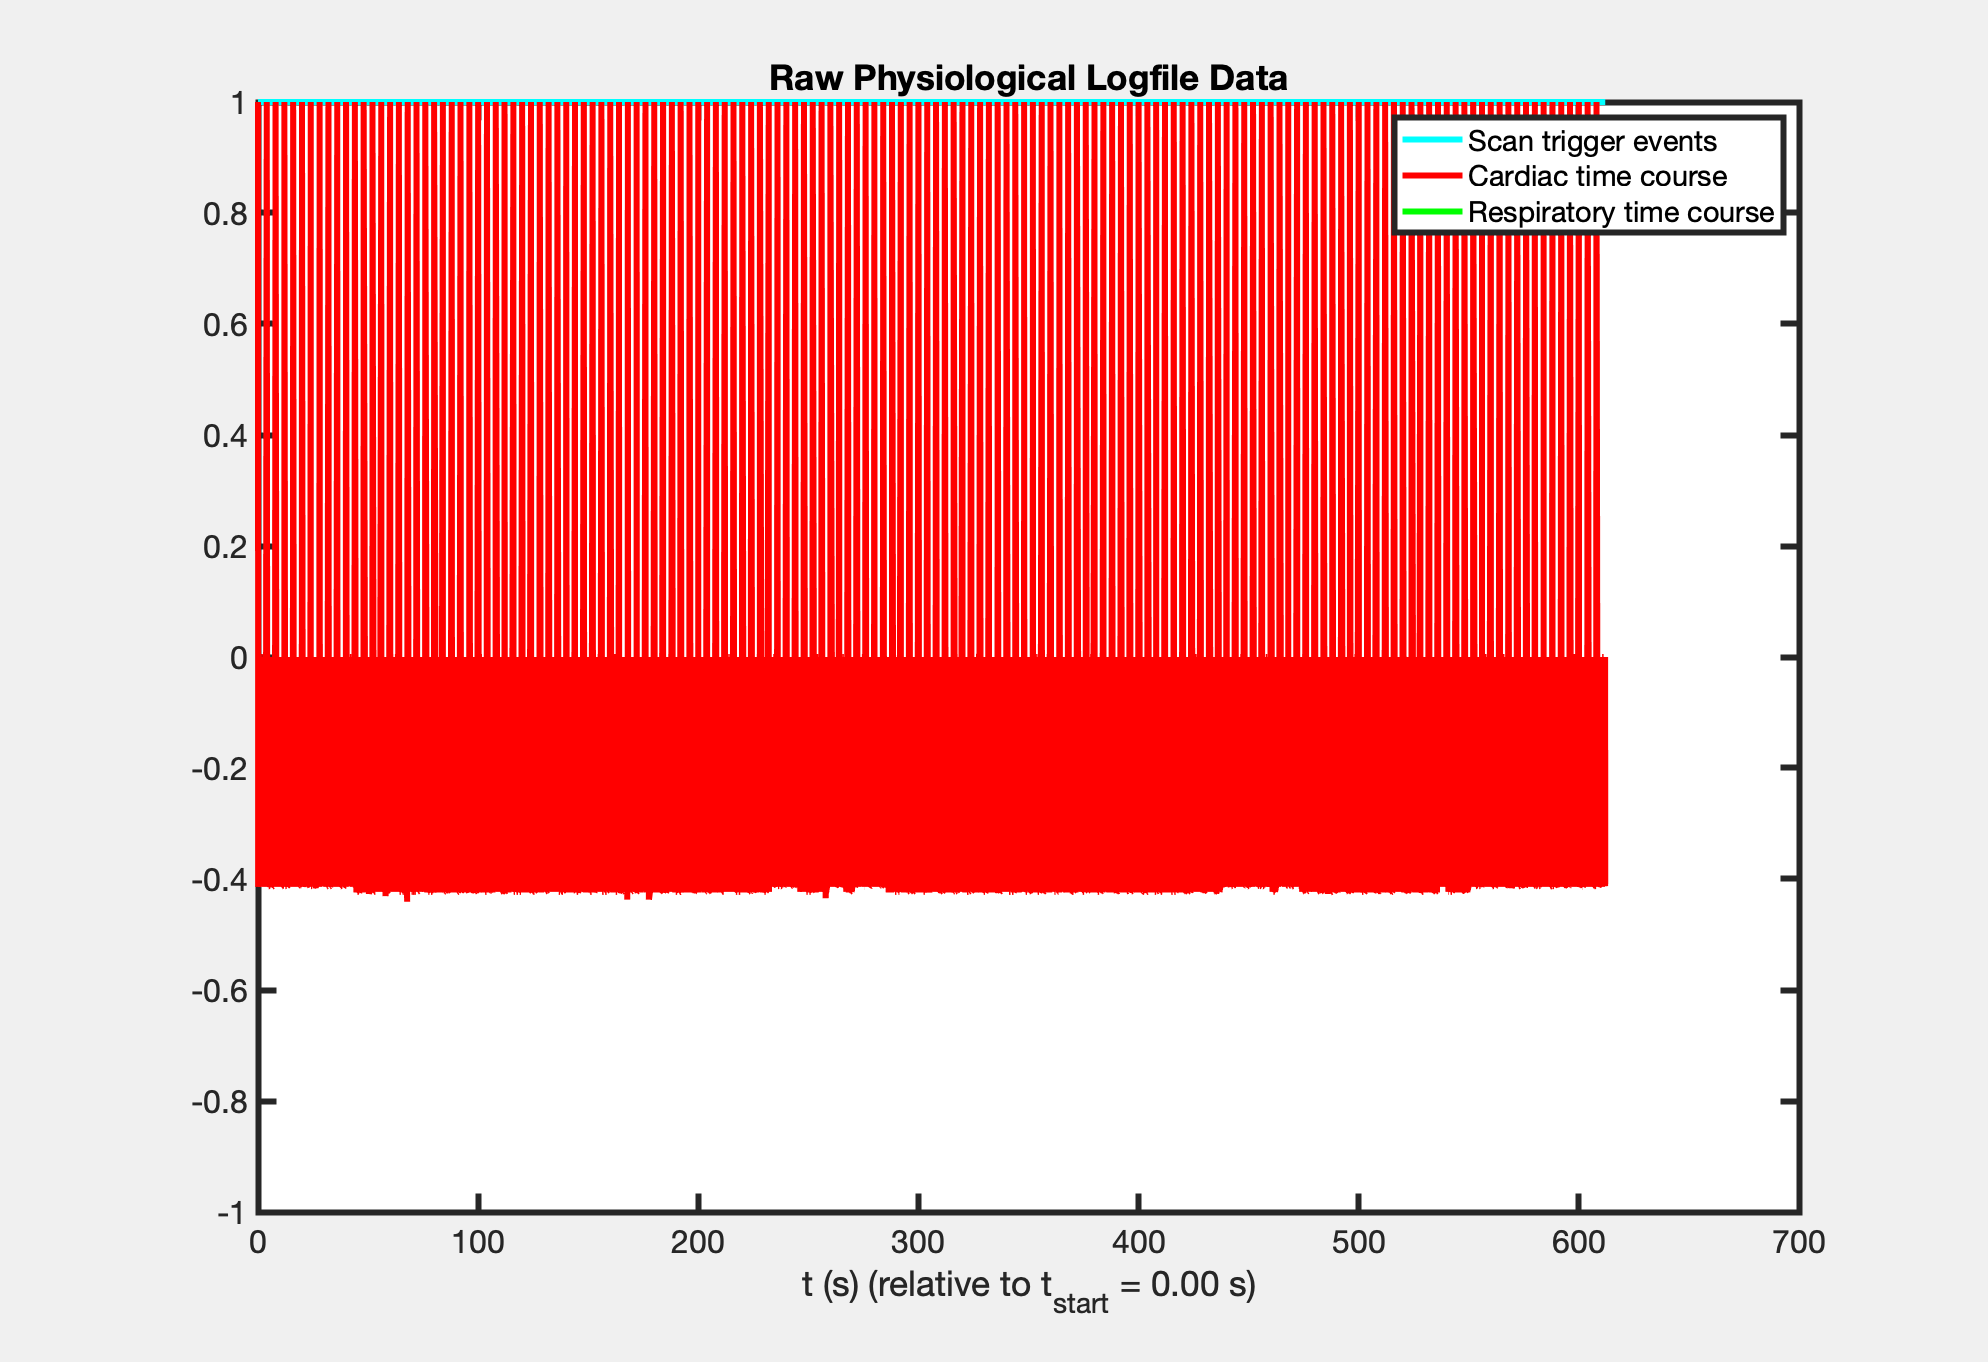

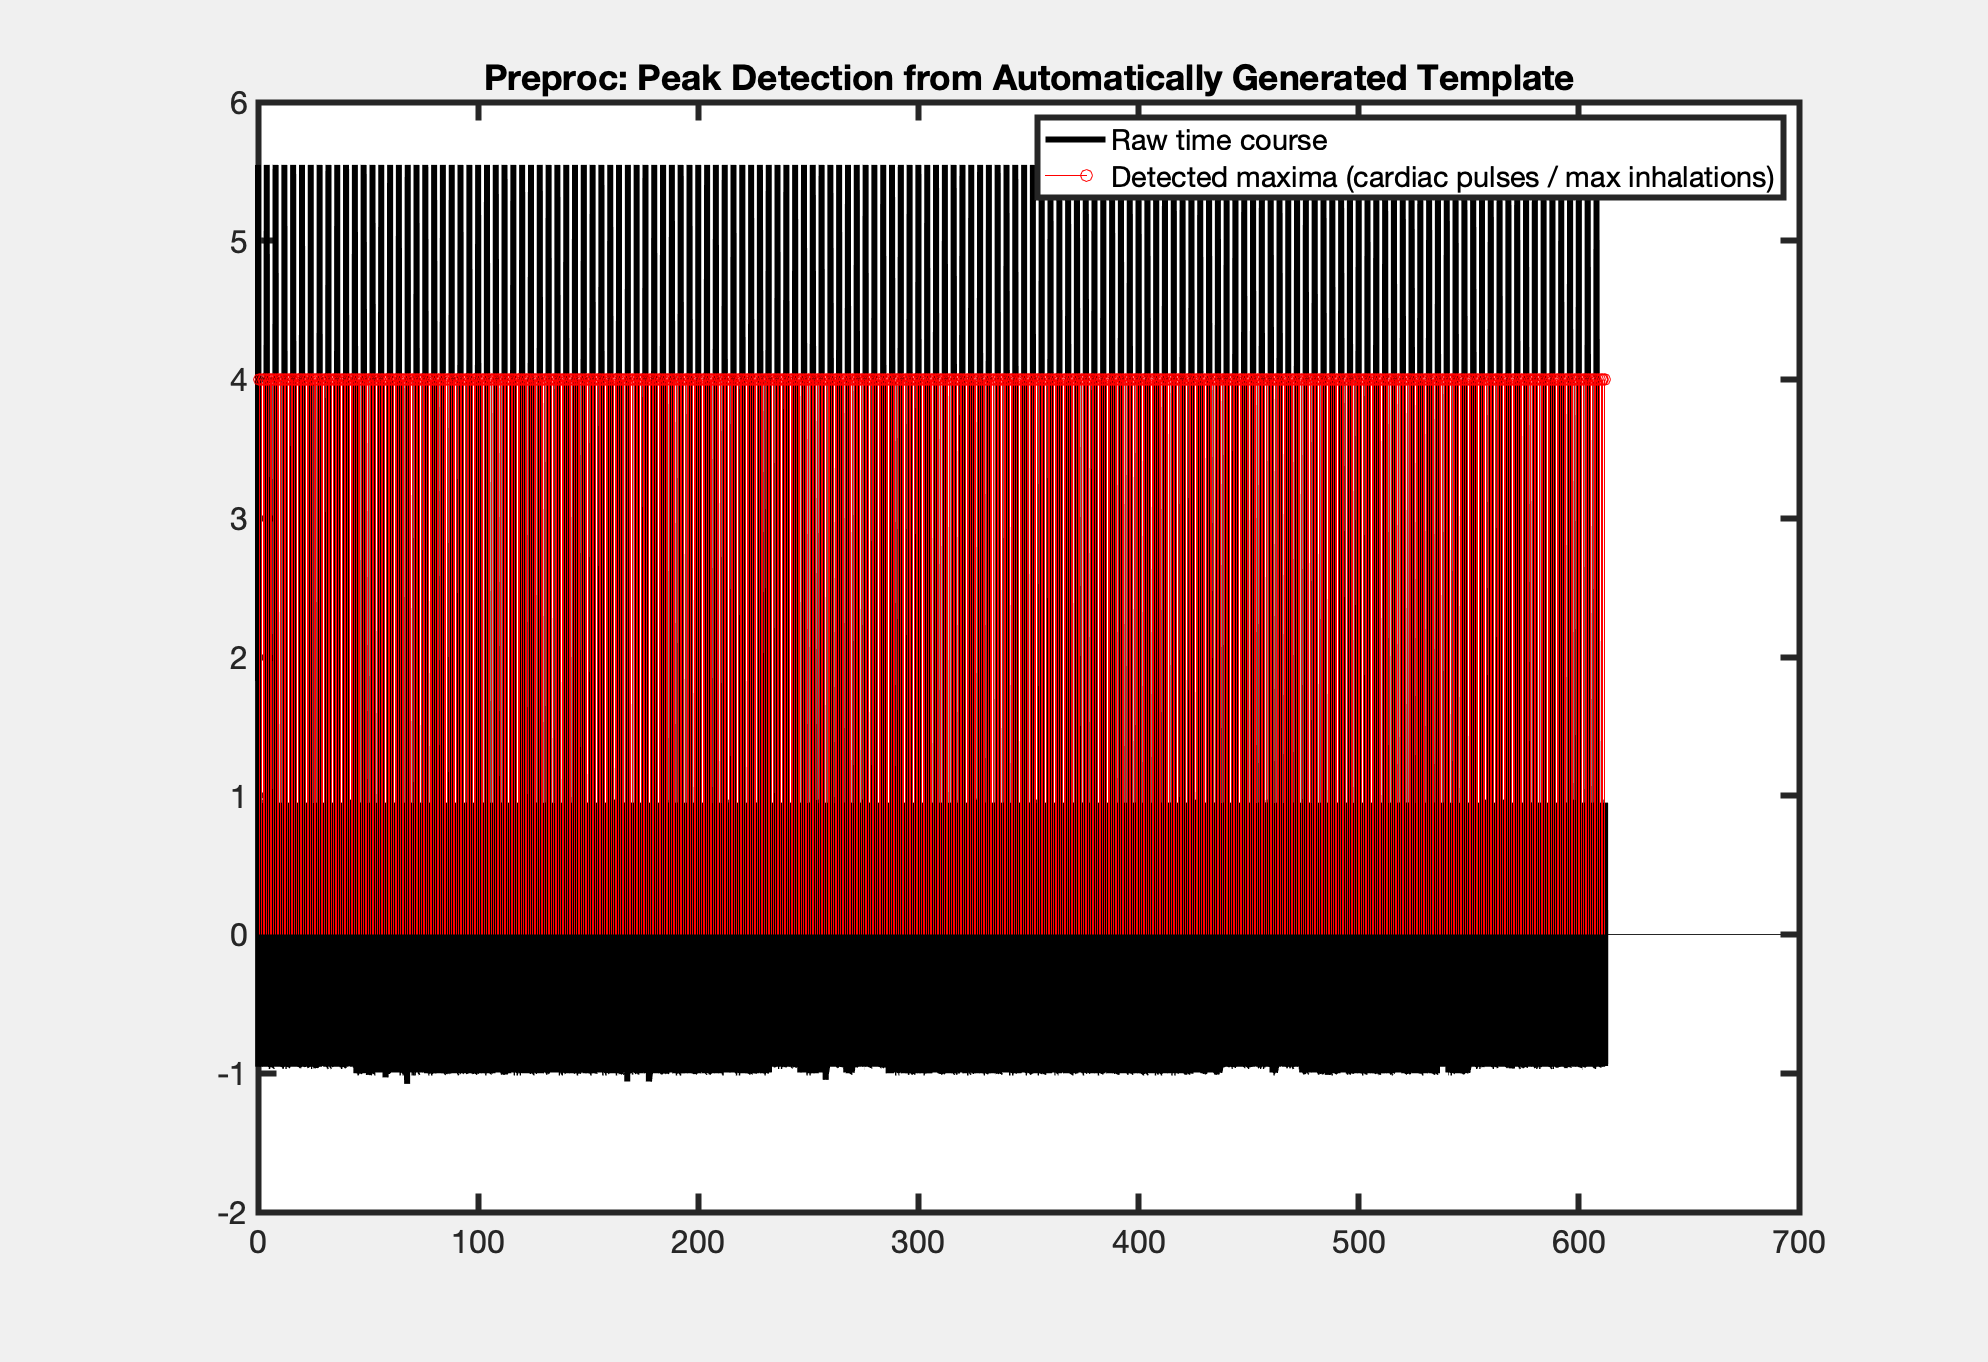

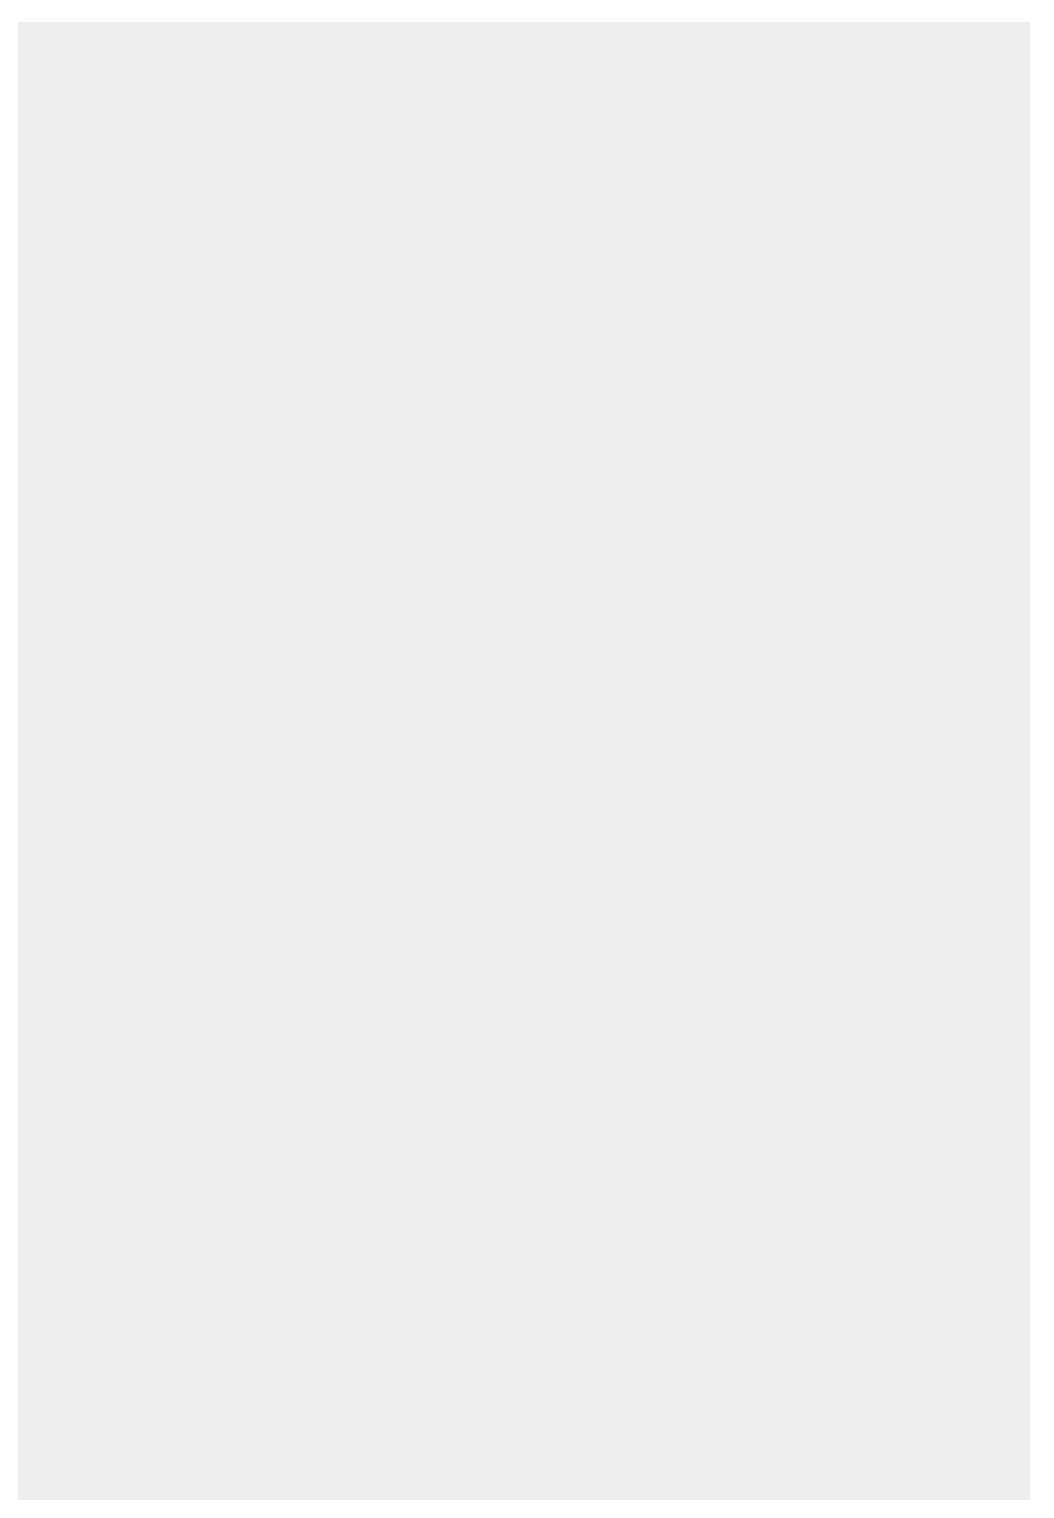

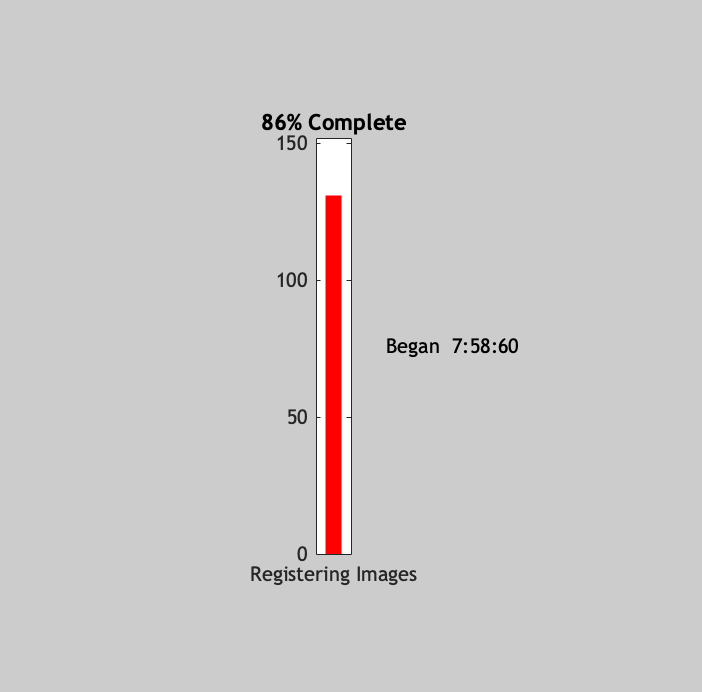

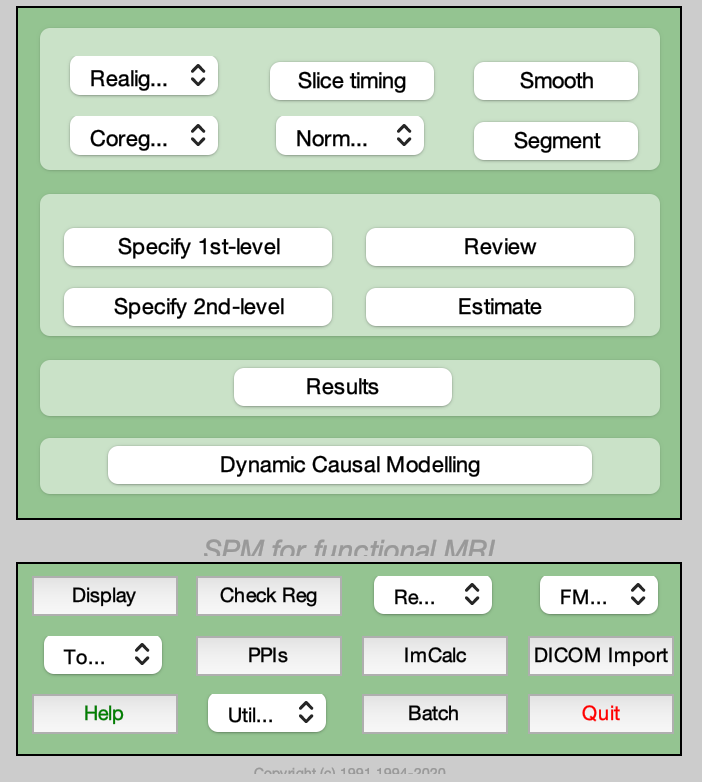

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% loads matlabbatch and adapts subject-specific data
clear matlabbatch

%fileJobPhysio = 'physio_spm_job.m';
fileJobPhysio = 'physio_batch_job.m';

% clear matlabbatch
run(fileJobPhysio)

spm_jobman(jobMode, matlabbatch)

if isInteractive, input('Press Enter to continue'); end



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## GLM with or w/o smoothing

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

if doSmooth
    fileJobGlm = 'glm_s3_spm_smooth_job.m'; % smooth
else
    fileJobGlm = 'glm_spm_job.m'; % 
end
clear matlabbatch
run(fileJobGlm)


spm_jobman(jobMode, matlabbatch)

Item 'Scans', field 'val': Value must be either empty, a cellstr or a cfg_dep object.
Item 'Multiple regressors', field 'val': Value must be either empty, a cellstr or a cfg_dep object.


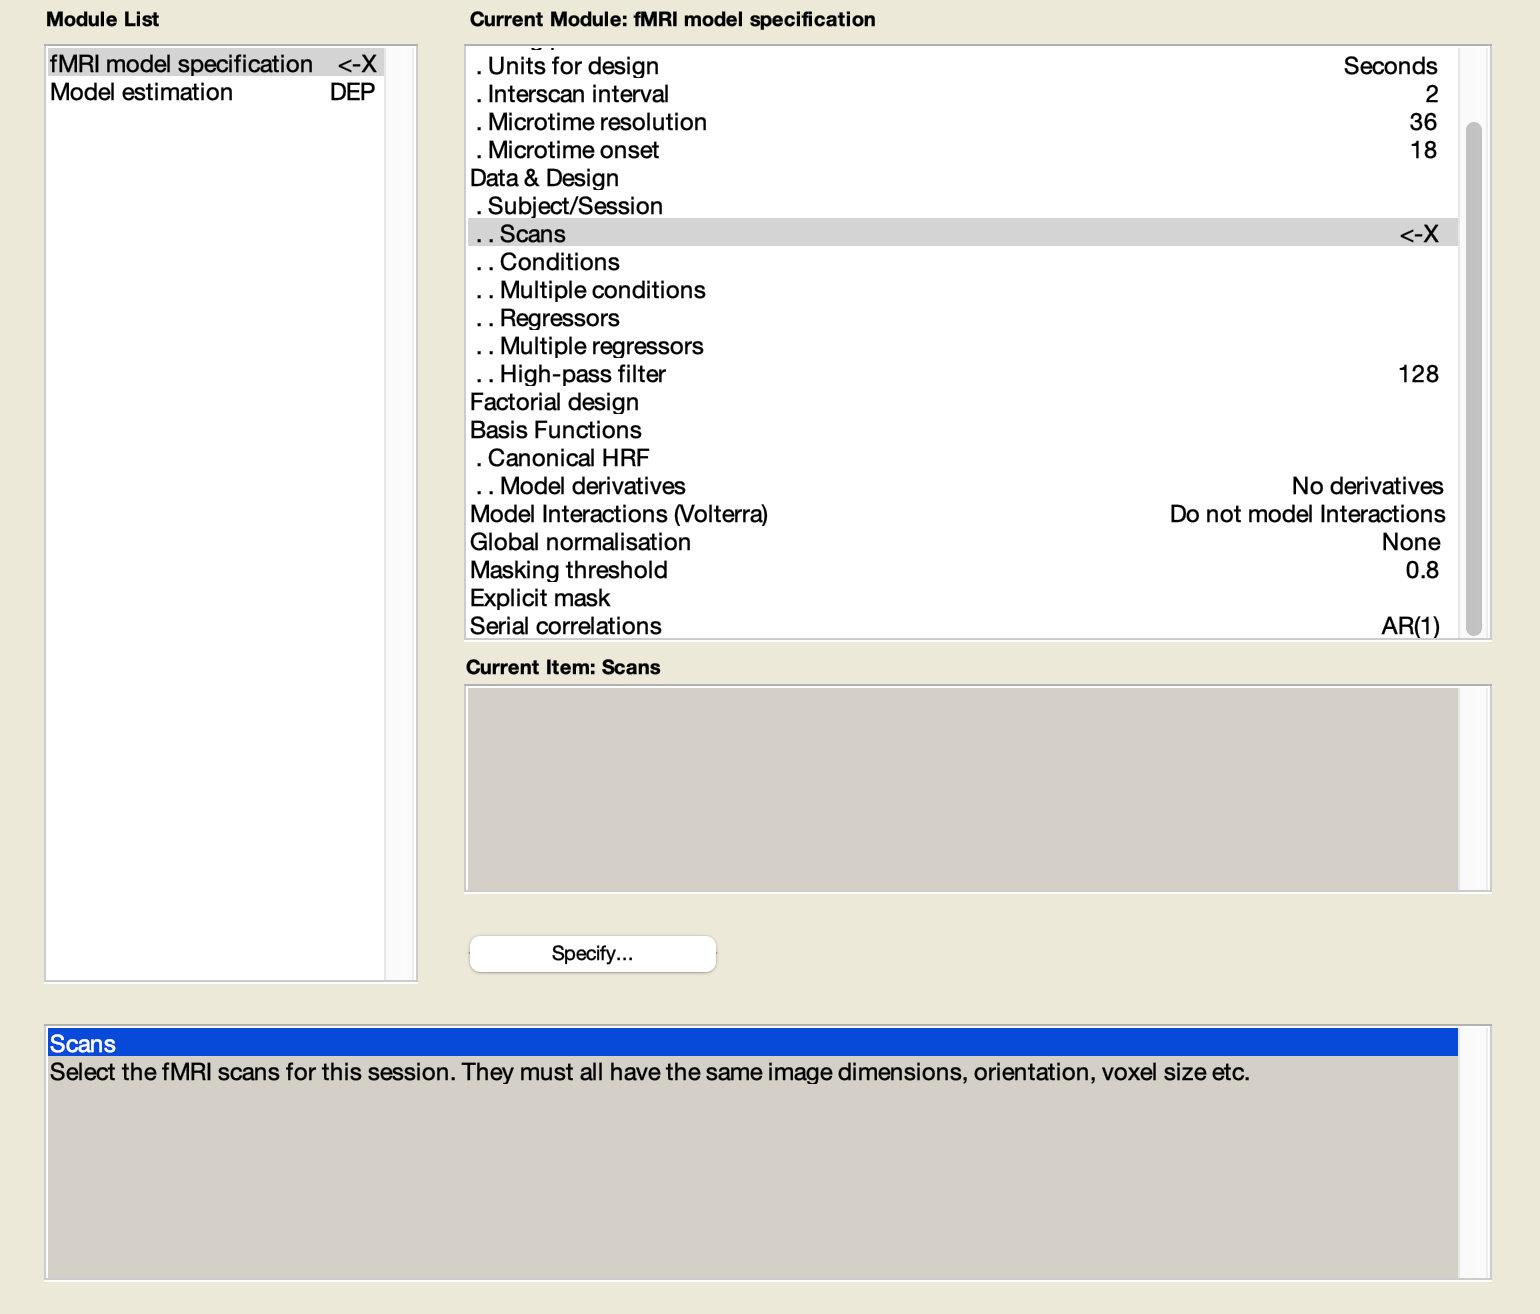


if isInteractive, input('Press Enter to continue'); end



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Visualize PhysIO contrasts

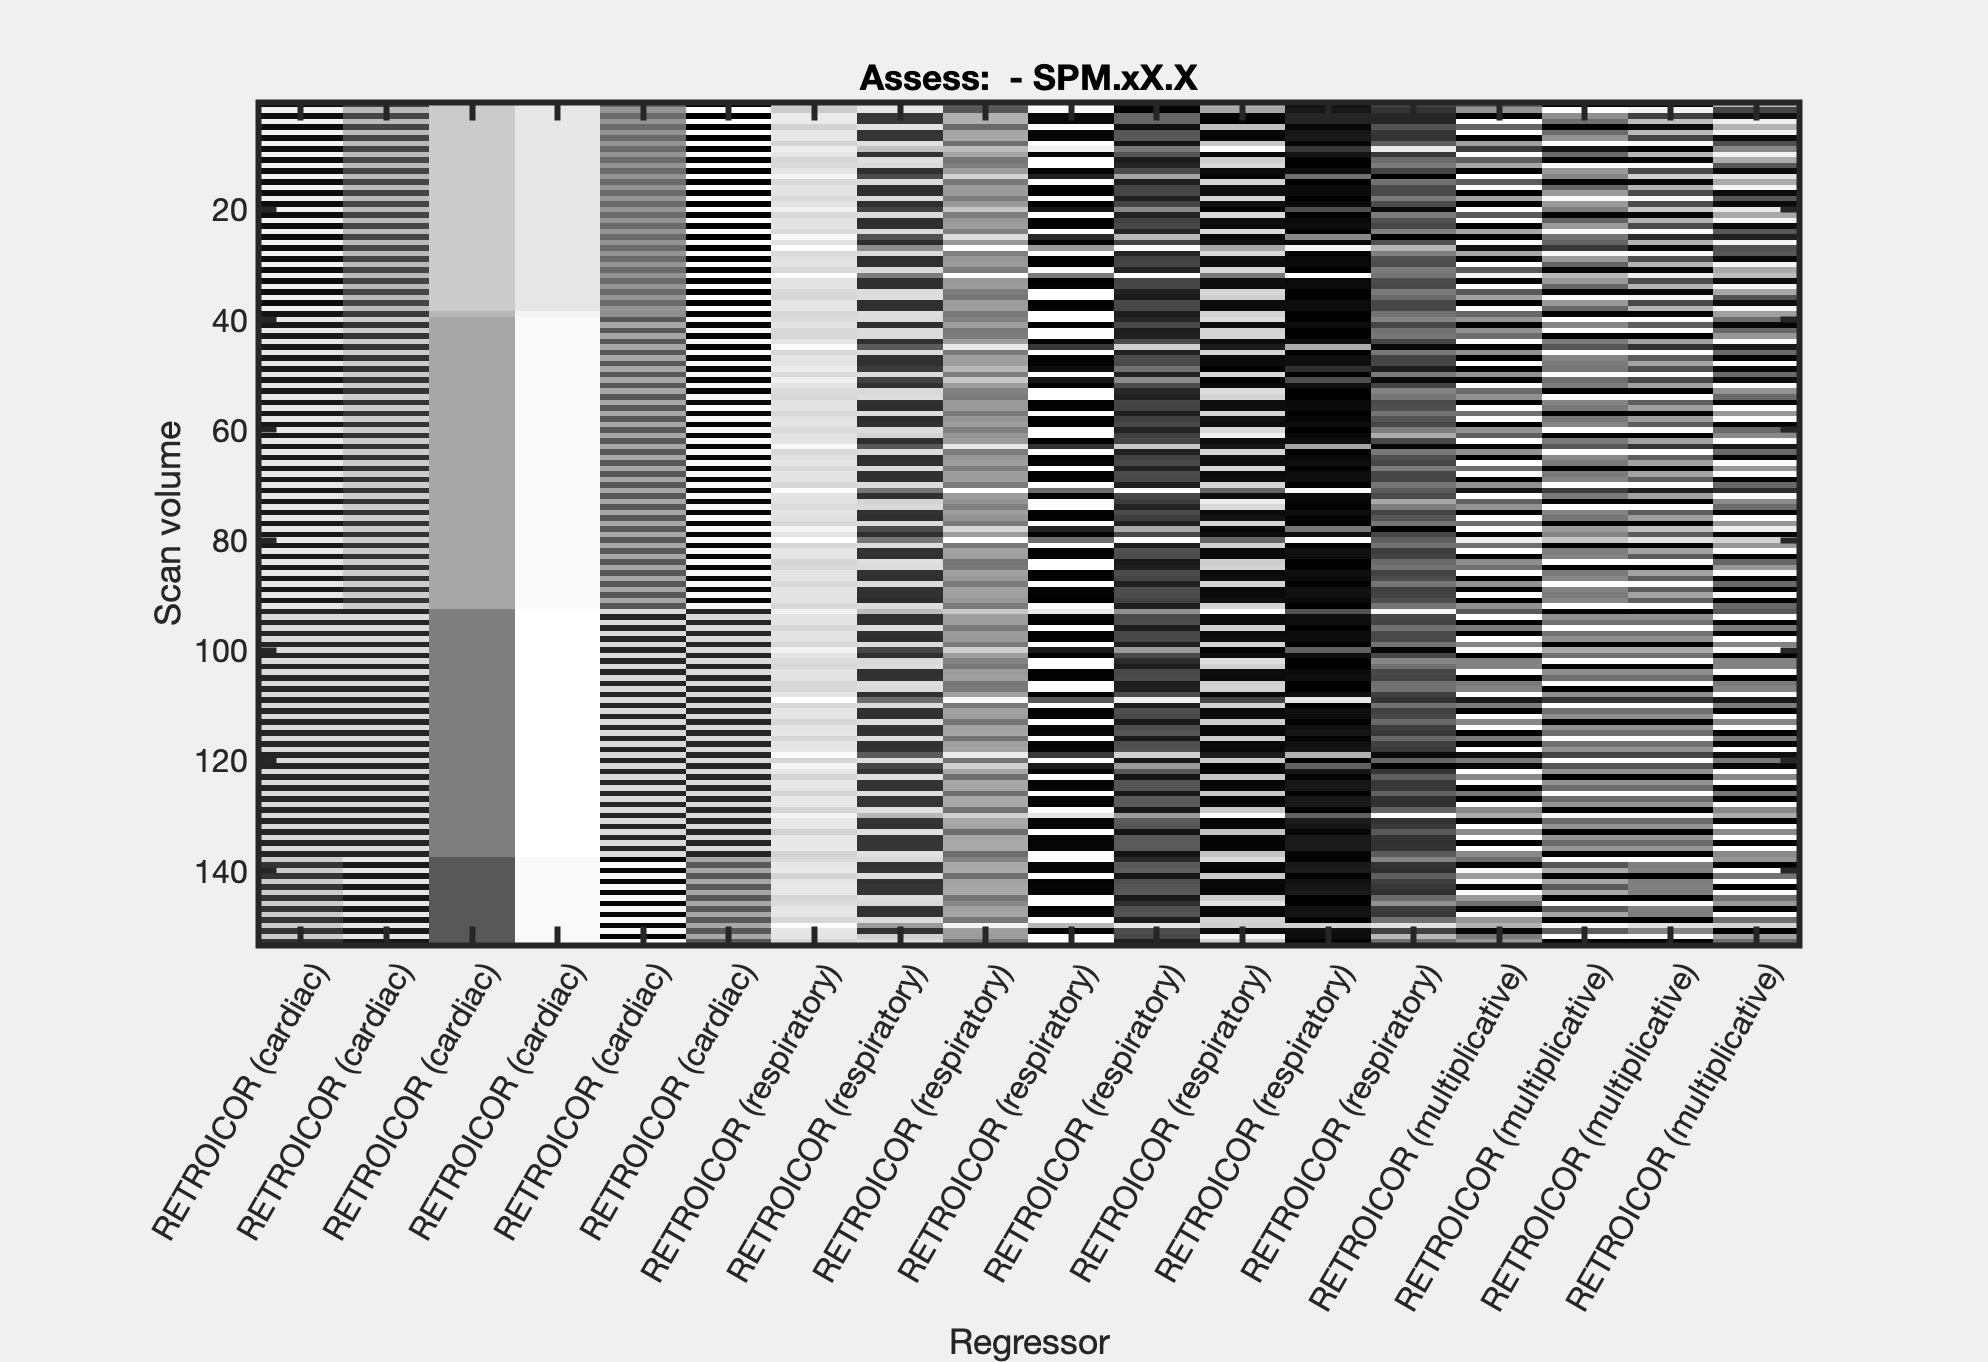

args = struct with fields:
         titleGraphicsWindow: ''
                  filePhysIO: 'physio_out/physio.mat'
                  fileReport: 'physio_out/physio.ps'
              fileStructural: 'nifti/mstruct.nii'
                     fileSpm: 'glm/SPM.mat'
               drawCrosshair: 1
          namesPhysContrasts: {9×1 cell}
      indReportPhysContrasts: [1 2 3 4 5 6 7 8 9]
     reportContrastThreshold: 1.0000e-03
    reportContrastCorrection: 'none'
           reportContrastMax: Inf
      reportContrastPosition: 'max'
               fovMillimeter: 0
         doPlotSliceParallel: 1
                   saveTable: 0
                       model: [1×1 struct]


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% automatic contrast creation using PhysIO
visualize_physio